% AE6511 Final Problem 7
% Tomoki Koike 
clear all; close all; clc;  % housekeeping commands
set(groot, 'defaulttextinterpreter','latex');
set(groot, 'defaultAxesTickLabelInterpreter','latex');
set(groot, 'defaultLegendInterpreter','latex');

## Settings

% State Parameters
auxdata.m = 38000;            % [kg] 
auxdata.mu = 3.986e14;        % [m^3/s^2]
auxdata.rho0 = 1.225;         % [kg/m^3]
auxdata.Hs = 7254.24;         % [m]
auxdata.r0 = 6371e3;          % [m]

% State Boundary Conditions 
h0 = 121.9e3;                 % [m]
hf = 30.48e3;                 % [m]
phi0 = deg2rad(-25);          % [rad]
phif_min = 0;                 % [rad]
phif_max = deg2rad(1200);     % [rad]
v0 = 7626;                    % [m/s]
vf = 908.15;                  % [m/s]
gamma0 = -deg2rad(-1.25);     % [rad]
gammaf_min = -deg2rad(6);     % [rad]
gammaf_max = 0;               % [rad]

t0 = 0;                       % [s]
tf_min = 100;                 % [s]
tf_max = 86400;               % [s]

% Control Bounds
alpha_min = -5;               % [deg]
alpha_max = 40;               % [deg]

% State Bounds for Optimization
h_bd = [0 200e3];                       % [m]
phi_bd = [phi0 phif_max];               % [rad]
v_bd = [400 10000];                     % [m/s]
gamma_bd = [-deg2rad(60) deg2rad(60)];  % [rad]

% Aircraft Characteristics
auxdata.S = 149.3881;                   % [m^2]
Lambda_max = 4e5;                       % [W/m^2]
q_max = 14500;                          % [kg/ms^2]
g0 = 9.81;                              % [m/s^2]
n_max = 5*g0;                           % [m/s^2]
auxdata.k_lambda = 9.4369e-5;           % [kg^0.5/m^1.5]

% Lift/Drag -> [deg]
auxdata.a0 = -0.20704;
auxdata.a1 = 0.029244;
auxdata.b0 = 0.07854;
auxdata.b1 = -0.61592e-2;
auxdata.b2 = 0.621408e-3;

## Define bounds

% Time
bounds.phase.initialtime.lower = t0;
bounds.phase.initialtime.upper = t0;
bounds.phase.finaltime.lower = tf_min;
bounds.phase.finaltime.upper = tf_max;

% Initial states
bounds.phase.initialstate.lower = [auxdata.r0+h0 phi0 v0 gamma0];
bounds.phase.initialstate.upper = [auxdata.r0+h0 phi0 v0 gamma0];

% Midway states
bounds.phase.state.lower = [auxdata.r0+h_bd(1) phi_bd(1) v_bd(1) gamma_bd(1)];
bounds.phase.state.upper = [auxdata.r0+h_bd(2) phi_bd(2) v_bd(2) gamma_bd(2)];

% Final states
bounds.phase.finalstate.lower = [auxdata.r0+hf phif_min vf gammaf_min];
bounds.phase.finalstate.upper = [auxdata.r0+hf phif_max vf gammaf_max];

% Controls
bounds.phase.control.lower = [alpha_min];
bounds.phase.control.upper = [alpha_max];

% Path
bounds.phase.path.lower = [0 0 0];
bounds.phase.path.upper = [Lambda_max q_max n_max];


## Guess

phif_guess = pi;
gammaf_guess = -deg2rad(4);
guess.phase.time = [t0; tf_max];
guess.phase.state(:,1) = [auxdata.r0+h0; auxdata.r0+hf];
guess.phase.state(:,2) = [phi0; phif_guess];
guess.phase.state(:,3) = [v0; vf];
guess.phase.state(:,4) = [gamma0; gammaf_guess];
guess.phase.control = [20; 20];

## Mesh

mesh.method = 'hp-LiuRao-Legendre';
mesh.tolerance = 1e-6;
mesh.maxiterations = 5;
mesh.colpointsmin = 4;
mesh.colpointsmax = 20;
mesh.sigma = 0.75;

## Solver

% Configure setup using the infromation provided
setup.name= 'HSvehicle-system'

setup = struct with fields:
    name: 'HSvehicle-system'


setup.functions.continuous = @HSvehicle_systemContinuous;
setup.functions.endpoint = @HSvehicle_systemEndpoint;
setup.displaylevel = 2;
setup.bounds = bounds;
setup.guess = guess;
setup.auxdata = auxdata;
setup.mesh = mesh;
setup.nlp.solver = 'ipopt';
setup.derivatives.supplier = 'sparseCD';
setup.derivatives.derivativelevel = 'second';
setup.method = 'RPM-Differentiation';

## Solve problem

output = gpops2(setup);

 ___________________________________________________________________ 
|                                                                   |
|            __________  ____  ____  _____        ________          |
|           / ____/ __ \/ __ \/ __ \/ ___/       /  _/  _/          |
|          / / __/ /_/ / / / / /_/ /\__ \ _____  / / / /            |
|         / /_/ / ____/ /_/ / ____/___/ //____/_/ /_/ /             |
|         \____/_/    \____/_/    /____/      /___/___/             |
|                                                                   |
| GPOPS-II Version 2.5.  Release Date: Aug 2018                     |
|___________________________________________________________________|
|                                                                   |
| GPOPS-II Copyright (c) 2013-2019 Michael Patterson & Anil V. Rao. |
|___________________________________________________________________|
|                                                                   |
| Downloading, using

## Plot Results

t = output.result.solution.phase.time;                  % time
x1 = output.result.solution.phase.state(:,1);           % r
x2 = output.result.solution.phase.state(:,2);           % phi
x3 = output.result.solution.phase.state(:,3);           % v 
x4 = output.result.solution.phase.state(:,4);           % gamma
u = output.result.solution.phase.control;               % alpha
lambda1 = output.result.solution.phase.costate(:,1);    % costate 1
lambda2 = output.result.solution.phase.costate(:,2);    % costate 2
lambda3 = output.result.solution.phase.costate(:,3);    % costate 3
lambda4 = output.result.solution.phase.costate(:,4);    % costate 4

% Compute Hamiltonian 
rho = auxdata.rho0*exp(-(x1 - auxdata.r0)/auxdata.Hs);
CD = auxdata.b0 + auxdata.b1*u + auxdata.b2*u.^2;
CL = auxdata.a0 + auxdata.a1*u;
D = 0.5*rho.*x3.^2*auxdata.S.*CD;
L = 0.5*rho.*x3.^2*auxdata.S.*CL;
m = auxdata.m;
mu = auxdata.mu;

H = (lambda1.*(x3.*sin(x4)) ...
    + lambda2.*(x3.*cos(x4)./x1) ... 
    + lambda3.*(-D/m - mu*sin(x4)./x1.^2) ...
    + lambda4.*(L/m./x3 - mu*cos(x4)./x1.^2./x3 + x3.*cos(x4)./x1)); 

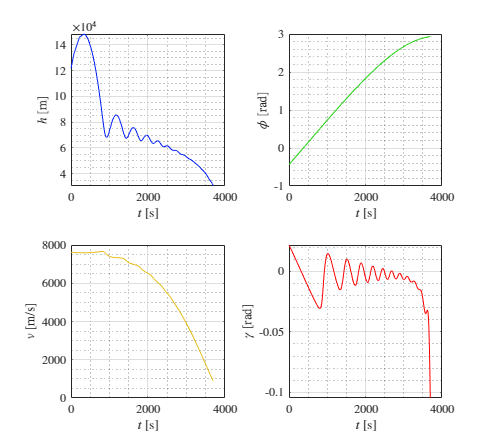

% Trajectories
fig = figure("Renderer","painters","Position",[60 60 1050 950]);
    subplot(2,2,1)
    plot(t,x1-auxdata.r0,'-','Color','#0320fc')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$h$ [m]')
    subplot(2,2,2)
    plot(t,x2,'-','Color','#1ecc0e')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$\phi$ [rad]')
    subplot(2,2,3)
    plot(t,x3,'-','Color','#e6be20')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$v$ [m/s]')
    subplot(2,2,4)
    plot(t,x4,'-','Color','#fc0303')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$\gamma$ [rad]')
saveas(fig,'outputs/p7_optStates.png')

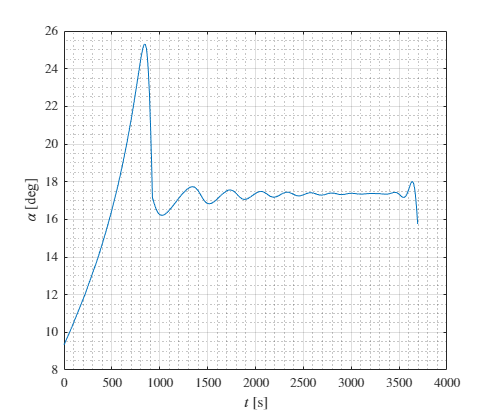

% Control
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(t,u)
    xlabel('$t$ [s]')
    ylabel('$\alpha$ [deg]')
    grid on; grid minor; box on;
saveas(fig,'outputs/p7_optControl.png')

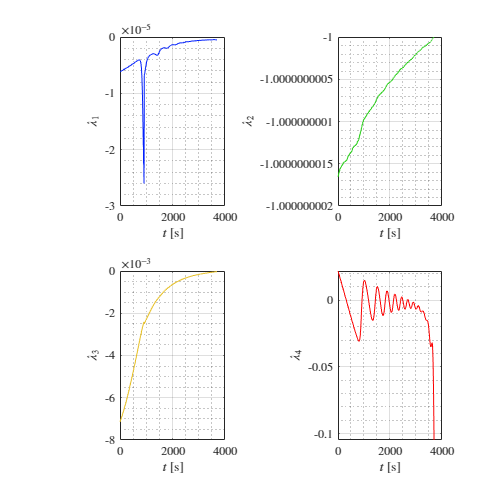

% Costates
fig = figure("Renderer","painters","Position",[60 60 950 950]);
    subplot(2,2,1)
    plot(t,lambda1,'-','Color','#0320fc')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$\lambda_1$')
    subplot(2,2,2)
    plot(t,lambda2,'-','Color','#1ecc0e')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$\lambda_2$')
    subplot(2,2,3)
    plot(t,lambda3,'-','Color','#e6be20')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$\lambda_3$')
    subplot(2,2,4)
    plot(t,x4,'-','Color','#fc0303')
    grid on; grid minor; box on;
    xlabel('$t$ [s]')
    ylabel('$\lambda_4$')
saveas(fig,'outputs/p7_optCostates.png')

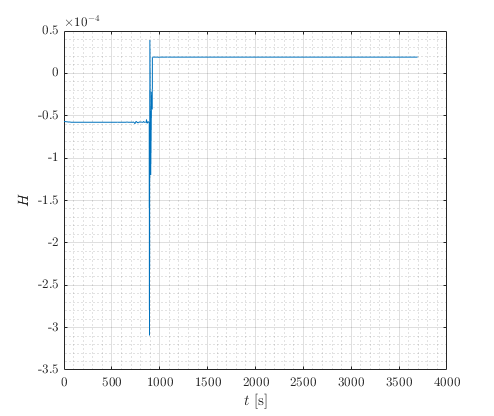

% Hamiltonian
fig = figure("Renderer","painters","Position",[60 60 950 800]);
    plot(t,H)
    xlabel('$t$ [s]')
    ylabel('$H$')
    grid on; grid minor; box on;
saveas(fig,'outputs/p7_optHamiltonian.png')

## Dynamics and Objectives

function phaseout = HSvehicle_systemContinuous(input)
    r = input.phase.state(:,1);
    phi = input.phase.state(:,2);
    v = input.phase.state(:,3);
    gamma = input.phase.state(:,4);
    alpha = input.phase.control(:,1);  % [deg]
    
    % Parameters
    mu = input.auxdata.mu;
    m = input.auxdata.m;
    S = input.auxdata.S;
    rho0 = input.auxdata.rho0;
    r0 = input.auxdata.r0;
    Hs = input.auxdata.Hs;
    a0 = input.auxdata.a0;
    a1 = input.auxdata.a1;
    b0 = input.auxdata.b0;
    b1 = input.auxdata.b1;
    b2 = input.auxdata.b2;
    k_lambda = input.auxdata.k_lambda;

    % Air density
    rho = rho0.*exp(-(r-r0)./Hs);

    % Lift/Drag
    CD = b0 + b1.*alpha + b2.*alpha.^2;
    CL = a0 + a1.*alpha;
    L = 0.5*rho.*v.^2*S.*CL;
    D = 0.5*rho.*v.^2*S.*CD;
    
    % Dynamics
    dr = v.*sin(gamma);
    dphi = v.*cos(gamma)./r;
    dv = -D/m - mu*sin(gamma)./r.^2;
    dgamma = L/m./v - mu*cos(gamma)./r.^2./v + v.*cos(gamma)./r;

    % Path
    Lambda = k_lambda*sqrt(rho).*v.^3;  % heating
    q = 0.5*rho.*v.^2;                  % dynamic pressure
    n = sqrt(L.^2 + D.^2)/m;            % normal load

    phaseout.path = [Lambda q n];
    phaseout.dynamics = [dr dphi dv dgamma];
end

function output = HSvehicle_systemEndpoint(input)
    % Maximize phi(t_f) == Minimize -phi(t_f)
    output.objective = -input.phase.finalstate(2);
end